**1.1A)**

% First, define all relevant variables:
load('../models/smallModel.mat'); % The model is stored in the 'model' subfolder
% To simplify later commands, define all relevant variables based on the
% information inside the model.
S   = model.S; % The S-matrix
b   = model.b; % Vector indicating which metabolites are boundary metabolites or not
c   = model.c; % Vector indicating which reaction is the objective function or not
LB  = model.lb; % Vector with lower bounds
UB  = model.ub; % Vector with upper bounds
REV = model.rev; % Vector indicating which reactions are reversible

**1.1B)**

num_mets = length(model.mets);
disp(['Number of metabolites: ' num2str(num_mets)])

Number of metabolites: 52


**1.1C) **

**1.2A)**

rev_Rxns = find(REV); % Find out which reactions are noted as reversible
numb_rev_Rxns = length(rev_Rxns); % Find out how many reactions are noted as reversible
disp(['Number of reversible reactions: ' num2str(numb_rev_Rxns)])

Number of reversible reactions: 17


inconsistencies = rev_Rxns(logical(REV(rev_Rxns).*LB(rev_Rxns))==0);
disp(['Reversibility inconsistency found in: ' model.rxnNames{inconsistencies}])

Reversibility inconsistency found in: Enolase


**1.2B)**

rxns=model.rxns;
for i=length(numb_rev_Rxns);
    rxns_rev(i,:)=rxns(rev_Rxns);
end
display(rxns_rev')

  17×1 cell array

    {'FBA'      }
    {'TPI'      }
    {'GLD'      }
    {'PGK'      }
    {'GPM'      }
    {'ENO'      }
    {'RPI'      }
    {'RPE'      }
    {'TKI1TKI2a'}
    {'TAL1'     }
    {'TKI1TKI2b'}
    {'ADH1'     }
    {'ACO'      }
    {'LSC1LSC2' }
    {'FUM1'     }
    {'MDH1'     }
    {'CO2TRANS' }



**1.2C)**

LB(17)=-1000;
inconsistencies = rev_Rxns(logical(REV(rev_Rxns).*LB(rev_Rxns))==0);
disp(['Reversibility inconsistency found in: ' model.rxnNames{inconsistencies}])

Reversibility inconsistency found in: 


**1.3A)**

v = S\b

v =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


**1.3B)**

**1.4A)**

pos(1) = find(strcmp(model.rxnNames,'Glucose exchange'));
pos(2) = find(strcmp(model.rxnNames,'O2 exchange'));
pos(3) = find(strcmp(model.rxnNames,'Biomass exchange'));
pos(4) = find(strcmp(model.rxnNames,'CO2 exchange'));
pos(5) = find(strcmp(model.rxnNames,'Acetate exchange'));
pos(6) = find(strcmp(model.rxnNames,'Ethanol exchange'));
pos(7) = find(strcmp(model.rxnNames,'Glycerol exchange'));

disp(['glcEX: LB = ' num2str(LB(pos(1))) '; UB = ' num2str(UB(pos(1)))])

glcEX: LB = -1; UB = 1000


disp(['o2EX: LB = '  num2str(LB(pos(2))) '; UB = ' num2str(UB(pos(2)))])

o2EX: LB = 0; UB = 1000


LB(pos(1)) = -1; % This is for glucose. Modify this line to make the
LB(pos(1)) = -1;
v = maximize(c,S,b,LB,UB); % A little function that runs linprog and

Optimal solution found.



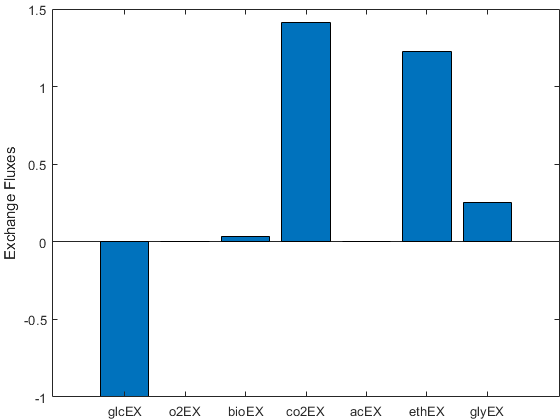

flux_names = {'glcEX','o2EX','bioEX','co2EX','acEX','ethEX','glyEX'};
barplot(v,pos,flux_names,[],'Exchange Fluxes',[])

**1.4B)**

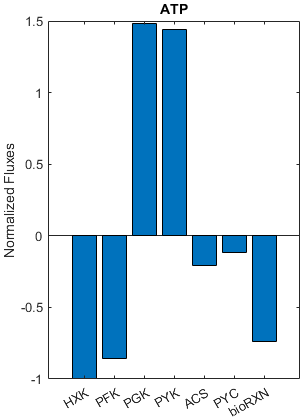

base=100;
[flux_ATP,plot_ATP] = plottedflux('ATP',model.mets,S,v);
barplot(flux_ATP,plot_ATP,model.rxns(plot_ATP),[],'Normalized Fluxes',base+200); title('ATP');

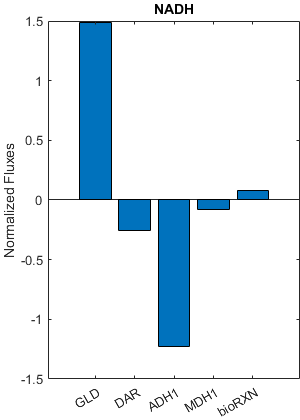

[flux_NADH,plot_NADH] = plottedflux('NADH',model.mets,S,v);
barplot(flux_NADH,plot_NADH,model.rxns(plot_NADH),[],'Normalized Fluxes',base+200); title('NADH');

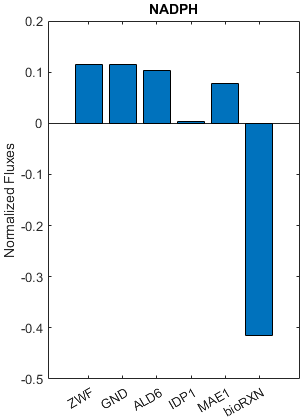

[flux_NADPH,plot_NADPH] = plottedflux('NADPH',model.mets,S,v);
barplot(flux_NADPH,plot_NADPH,model.rxns(plot_NADPH),[],'Normalized Fluxes',base+200); title('NADPH');

**2.1**

objFunc = find(c); % Find which reaction is the objective function
disp(['Reaction ' model.rxnNames{objFunc} ' is defined as objective function'])

Reaction Acetate exchange is defined as objective function


LB(pos(1)) = -1; % Ensure that glucose consumption is -1.
va         = maximize(c,S,b,LB,UB); % We store the result in vector va, to be used for plotting later

Optimal solution found.



**2.2**

c          = zeros(num_rxns,1); % First, set c=0 for all reactions
c(pos(5))  = +1; % And only set c=1 for the reaction we want as objective function
vb         = maximize(c,S,b,LB,UB); % We store the result in vector va, to be used for plotting later

Optimal solution found.



**2.3**

vc          = maximize(c,S,b,LB,UB);

Optimal solution found.



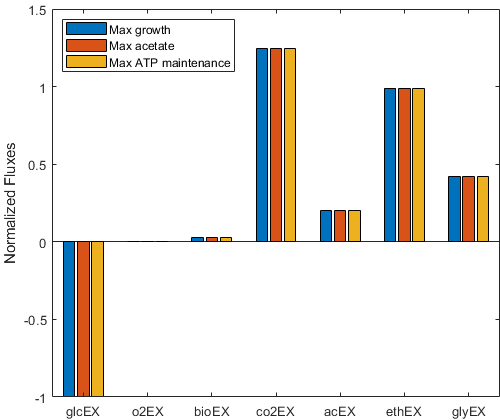

var_names = {'Max growth','Max acetate','Max ATP maintenance'};
barplot([va,vb,vc],pos,flux_names,var_names,'Normalized Fluxes',base+400)